# module 2: real EEG data simulation

in the previous module, we discussed how do we generate a complex wave and what are the arguments we need to know to start this simulation:

x number of frequencies (f),x number of amplitudes (amp), sampling frequency(srate), duration (set number, here is 5 sec).

since you have a complex wave, you need to determine a number of frequencies and amplitudes forming your complex wave.

in addition we needed to add some white noise. and this is a quick revision:

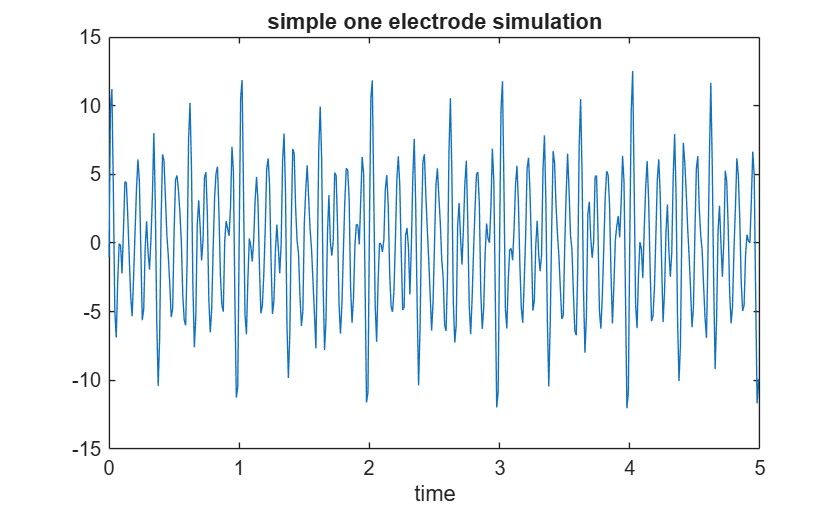

f = [10,15,18,12,16];
amp = [5,  3.5, 2.5, 1.5, 1];
srate = 90; 
t=0:1/srate:5-1/srate; 
%loop to build your complex wave
complex_wave = zeros(size(t));
for i = 1: length(f)
    complex_wave = complex_wave + amp(i)* sin(2*pi*f(i)*t);     
end
% add noise
noise1 = .5 * randn(size(t));
complex_wave_1 = complex_wave+ noise1;


figure;
plot(t,complex_wave_1)
xlabel('time')
title('simple one electrode simulation');

in this module we need to simulate the real EEG data. which is different

what are the differences?

- **number of channels:** you are measuring the signal from different channels not one. Each channel records a separate EEG signal from different brain region, which contain different frequency components and amplitudes.

- **random frequency and amplitude:** over trials, the signals are changing. practically you will never get the same results twice (for two trials).

- **noise:** you have noise changing over trials. for each trial you need to generate new random noise..

- **source mixing:** when you are measuring the signal, you are NOT measuring the signal from region of interest only, but you're measuring other signals from neighboring regions performing other tasks. (we will add this point in next module)

Your EEG data will be described through the number of channels (EEG_nbchan), number of trials (EEG_trials), and time vector (t).

srate = 500;
dur = 5;
numchannels = 32;
eeg_trials = 1;
eeg_pnts = srate * dur;
t = 0:1/srate:dur-1/srate;

our EEG signal will be like:

**EEG Data = Channels × Trials × Timepoints**

## **1. simulation of different channels:**

- in the previous simulation, we assumed that we have a signal source produces a combination of waves with predefined frequencies. f=one fixed number, manually assigned.

- But manually specifying every frequency for every channel would become impractical. For example, imagine that we have 32 channels, and each channel contains 5 frequency components. We would need to specify 160 frequency values manually, even before considering multiple trials. Therefore, instead of manually assigning every frequency, we need an automated way to generate frequency values.

- let's fix this problem using randomization.

%define the number of channels and the number of frequency components.
numfrequencies = 5;

% Generate random frequencies

frequencies = 5 + (30 - 5) * rand(numchannels, numfrequencies);

Here:

- `rand` generates random values between 0 and 1.

- Multiplication and addition scale these values to the range of 5–30 Hz.

- Each row represents one channel.

- Each column represents one frequency component.

frequencies(1,:)   % Frequencies of channel 1

ans =     8.9876   19.9703   23.1821   19.0057   10.8817


frequencies(2,:)   % Frequencies of channel 2

ans =     8.7557   20.6411   15.4211    8.9491   19.3528


**Important note:** This is only an introductory randomization example. It does not represent realistic EEG frequency distributions because all the channels are having frequencies between 5 and 30 Hz.

## **2. Frequency and amplitude variability:**

Different EEG channels do not necessarily contain the same frequency components with the same prominence.

For example, during a particular task:

- One channel might show prominent alpha activity.

- Another channel might show stronger beta activity.

- A third channel might contain a combination of alpha, beta, and theta activity.

This depends on the brain activity contributing to each recorded channel.

Therefore, we need to introduce two separate types of randomization.

## 2.1 Randomizing frequencies within each channel

EEG frequency bands are ranges not single fixed frequencies.

For example:

**Frequency band**

**Approximate range**

Delta

1–4 Hz

Theta

4–8 Hz

Alpha

8–13 Hz

Beta

13–30 Hz

Gamma

30–45 Hz

Instead of assigning the same frequency range to all channels, even if it's not matching with the activity expected from this region.

For example:

- Channel 1 might contain alpha activity at 9.5 Hz.

- Channel 2 might contain alpha activity at 11 Hz.

- Channel 3 might contain alpha activity at 12.3 Hz.

All three frequencies belong to the alpha band, but you assigned different values from different bands (theta, beta...etc).

so we need to randomly select a frequency from the expected frequency band.

%First, define the frequency bands.
bands = [
    1 4;    % Delta
    4 8;    % Theta
    8 13;   % Alpha
    13 30;  % Beta
    30 45   % Gamma
    ];

numchannels = 32;
numBands = size(bands,1);

frequencies = zeros(numchannels,numBands);

for ch = 1:numchannels

    for b = 1:numBands

        low = bands(b,1);
        high = bands(b,2);
        %the same equation we used to generate random frequencies, 
        % but this time we are choosing from different bands 
        % not the same range for all channels (5-30 in previous example)
        frequencies(ch,b) = low + (high-low)*rand;

    end

end

Now, every channel has a different randomly selected frequency for each band.

## **2.2 Randomizing the weights (contribution of each frequency band to the signal from each channel)**

Selecting different frequencies is not enough.

We also need to consider how strongly each frequency component contributes to the final EEG signal.

Not all channels have the same frequency-band distribution.

We can generate random weights for every channel and frequency band.

weights = rand(numchannels,numBands);

% Normalize weights for each channel
weights = weights ./ sum(weights,2);

What happens here?

- `rand` generates random contributions.

- Each channel gets a different set of weights.

- Normalization makes the sum of weights for each channel equal to 1.

Now we can combine both steps to produce our final simulated channel signals.

signals = zeros(numchannels,eeg_trials,length(t));

for ch = 1:numchannels
    for tr = 1 : eeg_trials

        for b = 1:numBands
            wave = weights(ch,b) * sin(2*pi*frequencies(ch,b)*t);
            %wave is 2d, it needs to be changed to 3d to match with signals
            %use reshape function
            signals(ch,tr, :) = signals(ch,tr,:) + reshape(wave,1,1,[]);
        end
    end

end

Each channel now has:

- Its own frequency values.

- Its own frequency-band contributions.

- A resulting complex signal.  *

plot

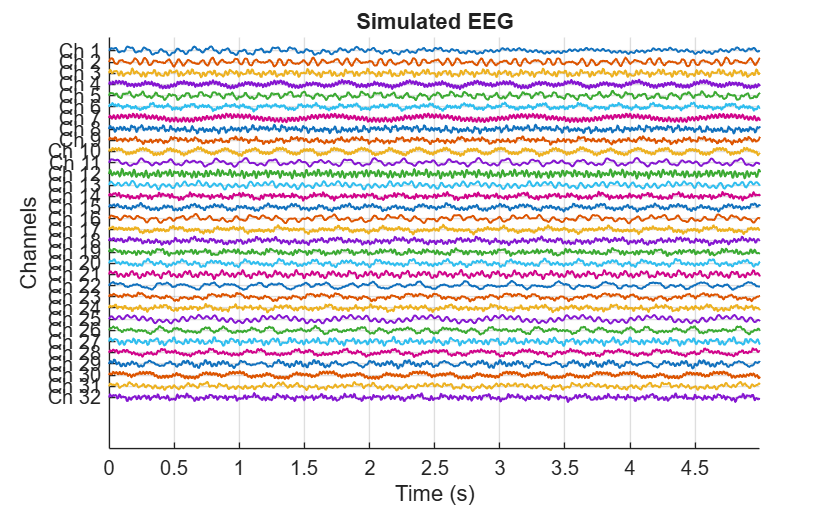

d = squeeze(signals(:, 1, : ));
off = max(abs(d(:))) * 2.2;
if off == 0, off = 1; end

figure('Color', 'w')
hold on
for ch = 1:numchannels
    plot(t, d(ch, :) + (numchannels - ch) * off, 'LineWidth', 1)
end
yticks((0:numchannels-1) * off)
yticklabels("Ch " + (numchannels:-1:1))
xlabel('Time (s)')
ylabel('Channels')
title('Simulated EEG')
xlim([t(1) t(end)])
grid on
hold off

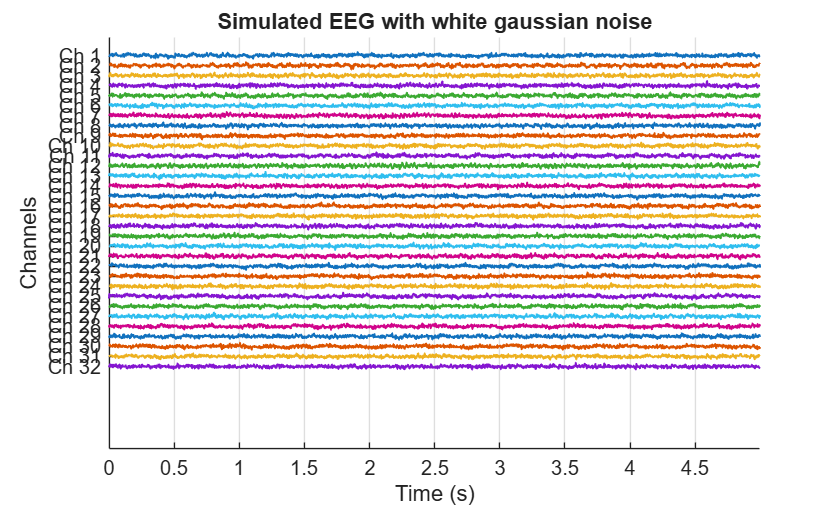

noise=.5*randn(numchannels,eeg_trials,eeg_pnts);
eeg_data = signals + noise;

%plot
d = squeeze(eeg_data(:, 1, :));
off = max(abs(d(:))) * 2.2;
if off == 0, off = 1; end

figure('Color', 'w')
hold on
for ch = 1:numchannels
    plot(t, d(ch, :) + (numchannels - ch) * off, 'LineWidth', 1)
end
yticks((0:numchannels-1) * off)
yticklabels("Ch " + (numchannels:-1:1))
xlabel('Time (s)')
ylabel('Channels')
title('Simulated EEG with white gaussian noise')
xlim([t(1) t(end)])
grid on
hold off

the previous part we were working on one trial

now we will move the generation of the frequencies to inside the loop to to generate new frequencies for each trial

in the next part change the number of trials to see hows the signal is changing

## Module 2: EEG signal simulation

srate = 500;
dur = 5;
numchannels = 32;
eeg_trials = 3;  % Change the number of trials here
eeg_pnts = srate * dur;
t = 0:1/srate:dur-1/srate;

## 1. Introductory randomization example

numfrequencies = 5;

frequencies = 5 + (30 - 5) * rand(numchannels, numfrequencies);

## 2. Frequency bands

bands = [
    1 4;    % Delta
    4 8;    % Theta
    8 13;   % Alpha
    13 30;  % Beta
    30 45   % Gamma
];

numBands = size(bands,1);

## 3. Generate EEG signals for all channels and trials

signals = zeros(numchannels, eeg_trials, length(t));

for tr = 1:eeg_trials

    % Randomize frequencies for each trial
    frequencies = zeros(numchannels, numBands);

    for ch = 1:numchannels
        for b = 1:numBands

            low = bands(b,1);
            high = bands(b,2);

            frequencies(ch,b) = low + (high-low)*rand;

        end
    end

    % Generate random weights for each trial
    weights = rand(numchannels, numBands);

    % Normalize weights for each channel
    weights = weights ./ sum(weights,2);

    % Combine frequency components
    for ch = 1:numchannels

        wave = zeros(size(t));

        for b = 1:numBands

            wave = wave + weights(ch,b) * ...
                sin(2*pi*frequencies(ch,b)*t);

        end

        signals(ch,tr,:) = wave;

    end

end

## 4. Plot the simulated EEG signals (without noise)

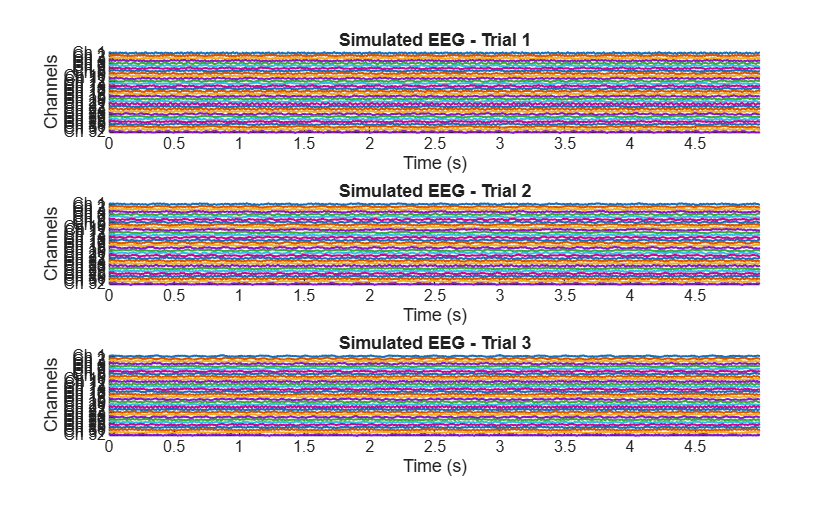

figure('Color', 'w')

off = max(abs(signals(:))) * 2.2;
if off == 0, off = 1; end

for tr = 1:eeg_trials

    d = reshape(signals(:,tr,:), numchannels, length(t));

    subplot(eeg_trials, 1, tr)
    hold on

    for ch = 1:numchannels
        plot(t, d(ch,:) + (numchannels-ch)*off, 'LineWidth', 1)
    end

    yticks((0:numchannels-1) * off)
    yticklabels("Ch " + (numchannels:-1:1))
    xlabel('Time (s)')
    ylabel('Channels')
    title(['Simulated EEG - Trial ' num2str(tr)])
    xlim([t(1) t(end)])
    grid on
    hold off

end

## 5. Add white Gaussian noise

noise = .5 * randn(numchannels, eeg_trials, eeg_pnts);
eeg_data = signals + noise;

## 6. Plot the simulated EEG signals with noise

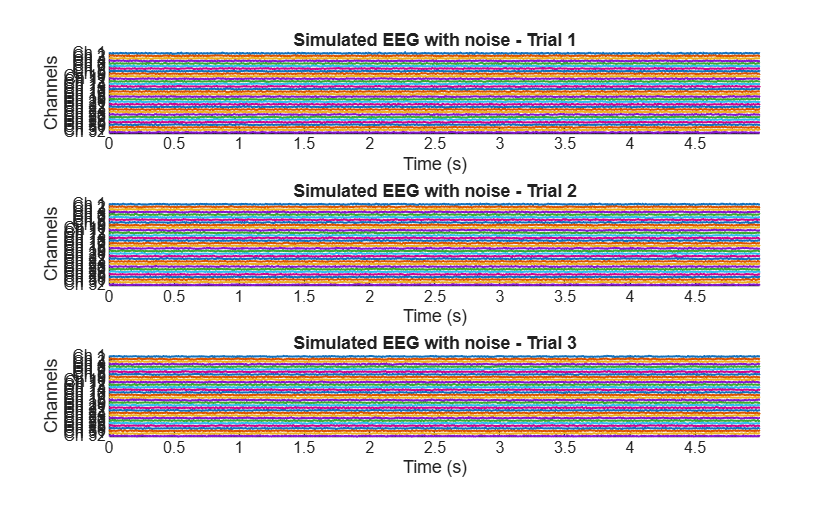

figure('Color', 'w')

off = max(abs(eeg_data(:))) * 2.2;
if off == 0, off = 1; end

for tr = 1:eeg_trials

    d = reshape(eeg_data(:,tr,:), numchannels, length(t));

    subplot(eeg_trials, 1, tr)
    hold on

    for ch = 1:numchannels
        plot(t, d(ch,:) + (numchannels-ch)*off, 'LineWidth', 1)
    end

    yticks((0:numchannels-1) * off)
    yticklabels("Ch " + (numchannels:-1:1))
    xlabel('Time (s)')
    ylabel('Channels')
    title(['Simulated EEG with noise - Trial ' num2str(tr)])
    xlim([t(1) t(end)])
    grid on
    hold off

end

%change the number of trials to any different number and see what will
%change